802.11ac SEM using [Disciplined Convex Programming](https://dcp.stanford.edu/)

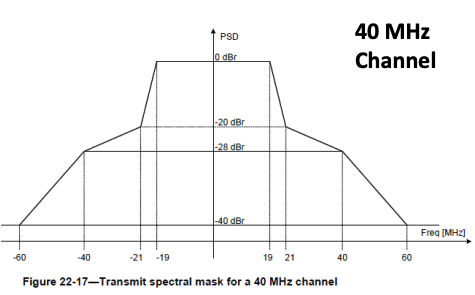

function SEM = ac_dcp(deltaf, f_range, B)
    % Generate only the positive part
    f = f_range(1):deltaf:f_range(2);
    
    % SEM = min(0, -((40/(60-19))*B*f) + (-40+60*(40/(60-19))) ); % dB
    SEM = min(1, -((9/100)*B)*(f-0.5) + 0.1); % linear
    
    % Generate the negative part
    SEM = [fliplr(SEM(2:end)) SEM]';
end